# MTH305 Risk Management

# W7. Apply PCA to the term structure of interest rates

MATLAB is powerful in matrix manipulation, and it also has a built-in function 'pca' for the principal component analysis (PCA).

This file starts with matrix manipulation and aims to replicate the results in the textbook.

Section 3 and 4 are not required for assessment.

## 1. import data

clear
clc

filename = 'W07_demo_data.xlsx';   % if it is in the Files or Current Folder of MATLAB
y = readtable(filename, 'Sheet', 'Daily swap data', 'VariableNamingRule', 'preserve');

swap_date = y{:,1};
swaprate = y{:,2:9};   % level of interest rates, in percent
dswaprate = (swaprate(2:end,:) - swaprate(1:end-1,:)) *100;   % change of interest rates, in basis point

## 2. PCA via eigen-decomposition

### 2.1 calculate $X^TX$, where $X$ is $n\times d$

The dataset is usually standardised, i.e., subtracting the mean and dividing by the empirical standard deviation.

X = dswaprate;
[n, d] = size(X);

% % standardisation
% X = (X - mean(X))./std(X);

% textbook, demean only
X = X - mean(X);

% variance-covariance matrix
Sigma = X'*X/n;

### 2.2 eigen-decomposition of $X^TX$

% U: d-by-d matrix, matrix of eigenvectors
% Lambda: d-by-d matrix, diagonal elements are eigenvalues
[U, Lambda] = eig(Sigma);

% rank eigenvalues from highest to lowest
a = sortrows([diag(Lambda), (1:d)'], 'descend');
Lambda = diag(a(:,1));
U = U(:, a(:,2));

disp(U)

    0.2155   -0.5006   -0.6275    0.4867    0.1220   -0.2371    0.0113   -0.0342
    0.3308   -0.4286   -0.1294   -0.3538   -0.2125    0.6739   -0.1001    0.2360
    0.3721   -0.2670    0.1570   -0.4138   -0.0958   -0.3110    0.4132   -0.5637
    0.3915   -0.1095    0.2559   -0.1741   -0.0190   -0.5511   -0.4159    0.5117
    0.4040    0.0185    0.3554    0.2691    0.5948    0.2780   -0.3161   -0.3268
    0.3938    0.1935    0.1946    0.3361    0.0069    0.0999    0.6848    0.4215
    0.3756    0.3706   -0.0678    0.3047   -0.6836    0.0393   -0.2779   -0.2794
    0.3049    0.5544   -0.5750   -0.3978    0.3306   -0.0222    0.0070    0.0317



disp(Lambda)

  308.1330         0         0         0         0         0         0         0
         0   22.7428         0         0         0         0         0         0
         0         0    4.3161         0         0         0         0         0
         0         0         0    1.6681         0         0         0         0
         0         0         0         0    0.8346         0         0         0
         0         0         0         0         0    0.5366         0         0
         0         0         0         0         0         0    0.3090         0
         0         0         0         0         0         0         0    0.2787



% varaince of X explained by each factor
variance_explained = diag(Lambda) / sum(diag(Lambda));

% standard deviation of each factor
f_sigma = sqrt(diag(Lambda));


### 2.3 latent factor


$$F=XU$$


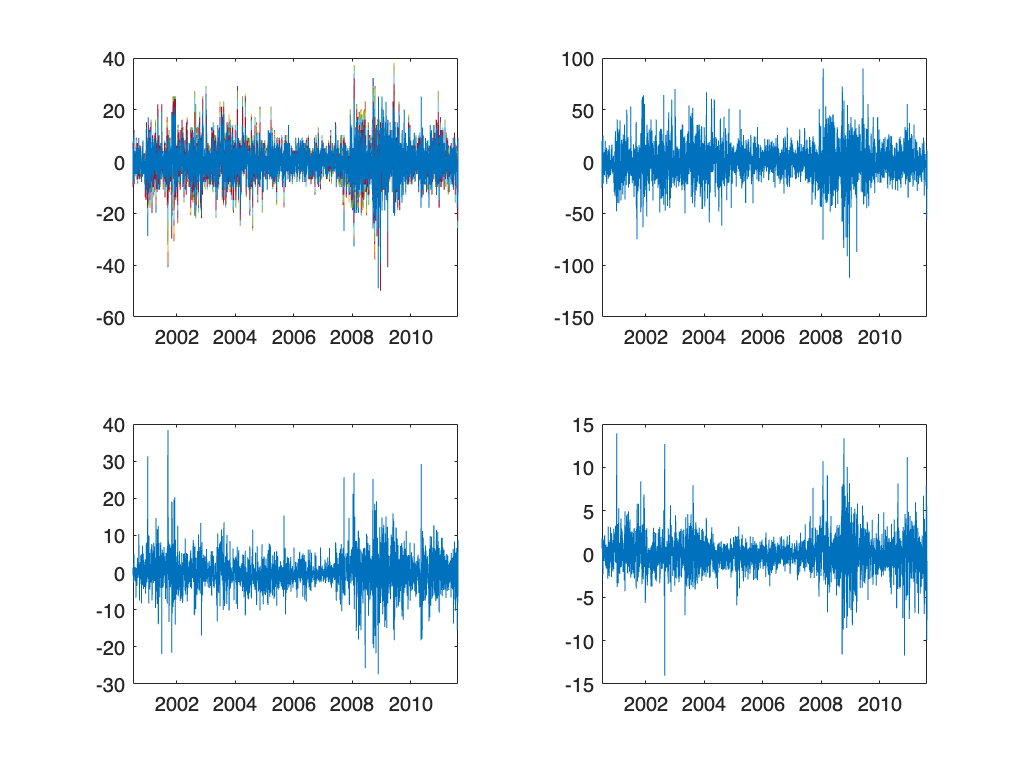

% factor
F = X*U;

% plot
tiledlayout(2,2)
nexttile
plot(swap_date(2:end),X)
nexttile
plot(swap_date(2:end),F(:,1))
nexttile
plot(swap_date(2:end),F(:,2))
nexttile
plot(swap_date(2:end),F(:,3))

## 3. PCA via MATLAB built-in function

You can of course use the built-in function 'pca', but you need to understand which output is for eigenvalue, eigenvector, etc.

For assessment of the module, it is recommended not to use this function unless you know exactly what it calculates.

% [coeff, score, latent, tsquared, explained, mu] = pca(X);
% INPUT
%    The rows of X correspond to observations, and the columns correspond to variables.
% OUTPUTS
%    coeff: eigenvectors (sign could be different from U)
%    latent: eigenvalues (diagonal of Lambda)
%    explained: lambda_k/sum(lambda)
%    score: latent factor (demeaned)
%           (sign could be different from f <-> sign difference between coeff and U)

## 4. PCA applied to the level of interest rates

X = swaprate;
X = (X - mean(X))./std(X);

[coeff, score, latent, tsquared, explained, mu] = pca(X);

disp(coeff)

    0.3392   -0.5172    0.5633    0.4510   -0.2994   -0.0750    0.0256   -0.0274
    0.3548   -0.3429    0.1413   -0.3242    0.6430    0.3784   -0.1600    0.2218
    0.3617   -0.1990   -0.1492   -0.3990    0.0584   -0.4100    0.3301   -0.6063
    0.3643   -0.0848   -0.2959   -0.2340   -0.3212   -0.3639    0.0132    0.6943
    0.3648    0.0138   -0.3407   -0.0124   -0.3863    0.3705   -0.6055   -0.3122
    0.3623    0.1734   -0.2924    0.3304   -0.0085    0.4703    0.6484    0.0480
    0.3547    0.3436   -0.1080    0.5126    0.4646   -0.4340   -0.2773   -0.0247
    0.3245    0.6479    0.5827   -0.3248   -0.1587    0.0632    0.0253    0.0070



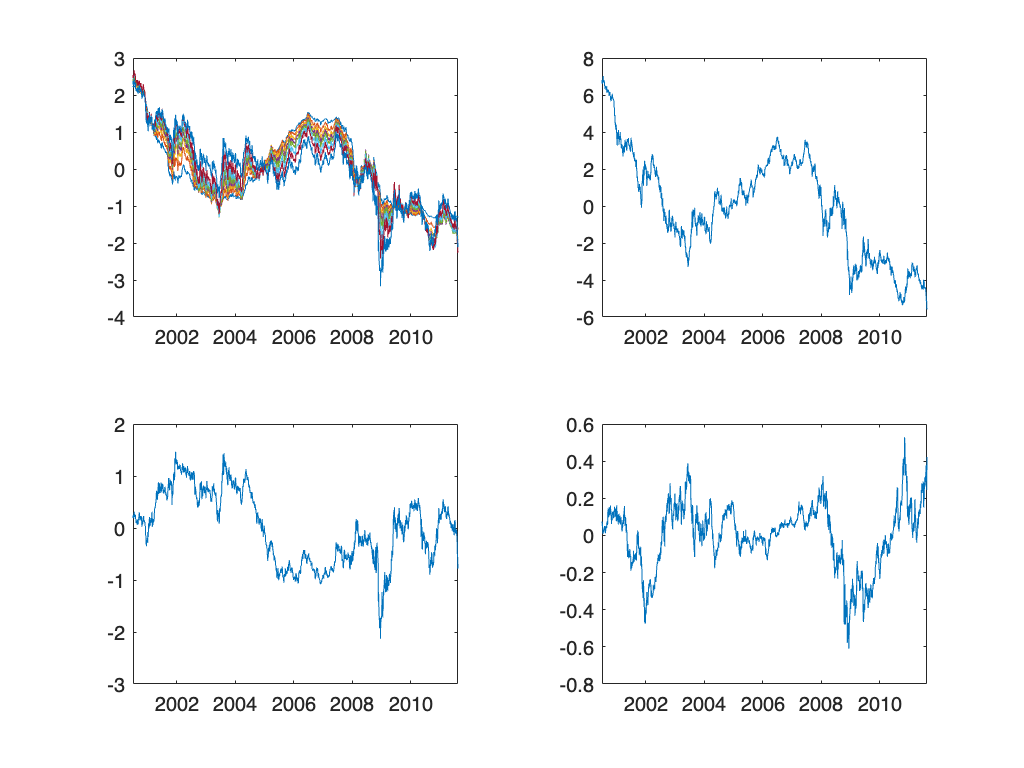

% plot
tiledlayout(2,2)
nexttile
plot(swap_date,X)
nexttile
plot(swap_date,score(:,1))
nexttile
plot(swap_date,score(:,2))
nexttile
plot(swap_date,score(:,3))